## 3 dimenziós FDM-hez tartozó együttható mátrix 3 dimenziós L tartományon

% belso pontok szama
N = 5;

% lepeshossz
h = 1/(N+1);
s = floor(N/2);

### Bal felső nagy négyzet

e = ones(N,1);
B = spdiags([-1*e,6*e,-1*e],[-1,0,1],N,N);
F = -1*speye(N);

Tmp1 = spdiags([e,e],[-1,1],N,N);
B_tilde = kron(speye(N),B) + kron(Tmp1,F);
%spy(B_tilde);
I = kron(speye(N),-1*speye(N));


big_square = kron(speye(s),B_tilde) +kron(spdiags([e,e],[-1,1],s,s),-1*speye(N^2));
big_square;

### A_1 és A_2 téglalapok

side_a = s*N+(N-s)*s;
side_b = N^2;

A_2 = zeros(side_b,side_a);
A_2(1:s*N,1:s*N) = kron(speye(s),-1*speye(N));
A_2 = sparse(A_2);

A_tmp = zeros(N,s);
A_tmp(N-s+1:N,:) = -1*speye(s);

for i = 0:(N-s-1)
    A_2(s*N+i*N+1:s*N+i*N+N,s*N+i*s+1:s*N+i*s+s) = A_tmp;
end
A_1 = sparse(A_2');
%full(A_1)
%full(A_2)

### D mátrix (2 dimenzióban L-alakú tartományon az együttható mátrix) - jobb alsó mátrix blokkdiagonálisának egy blokkja

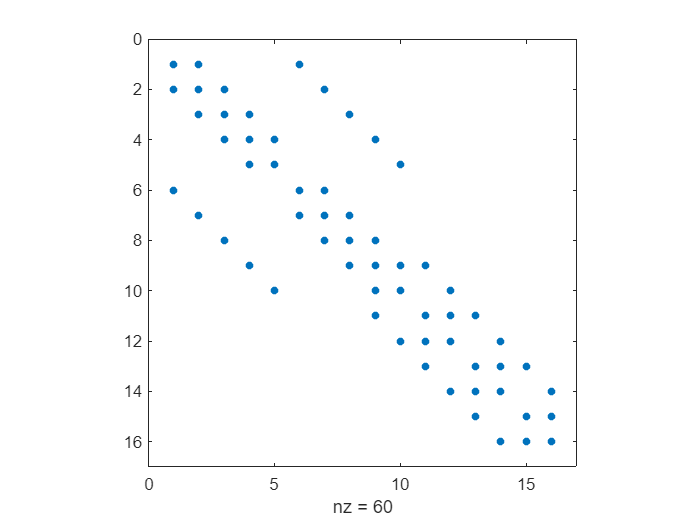

e_tmp = ones(N-s,1);
D = zeros(s*N+(N-s)*s,s*N+(N-s)*s);
D(1:s*N,1:s*N)=kron(speye(s),B) + kron(spdiags([e_tmp,e_tmp],[-1,1],s,s),-1*speye(N)); % bal felso resz feltoltese
e_hat = ones(s,1);
B_hat = spdiags([-1*e_hat,6*e_hat,-1*e_hat],[-1,0,1],s,s);

% jobb also negyzet feltoltese:
D(s*N+1:end,s*N+1:end) = kron(speye(N-s),B_hat)+kron(spdiags([-1*ones(N-s,1),-1*ones(N-s,1)],[-1,1],N-s,N-s),speye(s));


D((s-1)*N+(N-s)+1:(s-1)*N+(N-s)+s,s*N+1:s*N+s)=-1*speye(s);
D(s*N+1:s*N+s,(s-1)*N+(N-s)+1:(s-1)*N+(N-s)+s)=-1*speye(s);

D = sparse(D);

%full(D)
spy(D)

### Jobb alsó kisebb mátrix


small_square = kron(spdiags([e_tmp,e_tmp],[-1,1],N-s,N-s),-1*speye(side_a)) + kron(speye(N-s),D);
%full(small_square)

### Teljes mátrix feltöltése

%matrix_fdm = zeros(s*N^2+(N-s)*side_a,s*N^2+(N-s)*side_a);
matrix_fdm = sparse(s*N^2+(N-s)*side_a,s*N^2+(N-s)*side_a);
size(matrix_fdm)

ans =     98    98


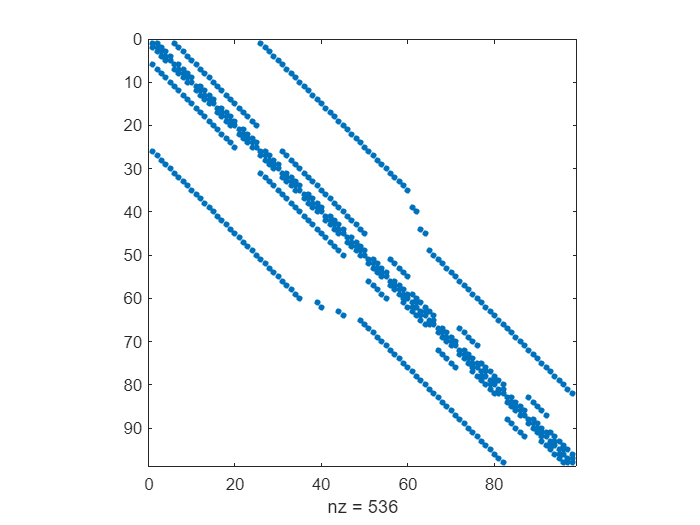

% bal felso negyzet
matrix_fdm(1:s*N^2,1:s*N^2) = big_square;

%A_2
matrix_fdm((s-1)*N^2+1:(s-1)*N^2+side_b,s*N^2+1:s*N^2+side_a) = A_2;

%A_1
matrix_fdm(s*N^2+1:s*N^2+side_a,(s-1)*N^2+1:(s-1)*N^2+side_b) = A_1;


%jobb alsó
e_tmp = ones(N-s,1);

matrix_fdm(s*N^2+1:end,s*N^2+1:end) = small_square;
matrix_fdm = sparse(matrix_fdm);
A_h = 1/h^2 * sparse(matrix_fdm);

spy(A_h)

### Numerikus értékek kiszámolása

%[xi,yj,zk] = meshgrid(h:h:1-h,h:h:1-h,h:h:1-h);
%tmp=sin(2*xi*pi).*sin(2*yj*pi).*sin(2*zk*pi);

[xi,yj,zk] = meshgrid(h:h:1-h,h:h:1-h,h:h:s*h);
tmp=sin(2*xi*pi).*sin(2*yj*pi).*sin(2*zk*pi);
size(tmp)

ans =      5     5     2


% f: jobb oldal
f = zeros(s*N^2+(N-s)*(s*N+(N-s)*s),1);

% u: pontos ertekek
u = zeros(s*N^2+(N-s)*(s*N+(N-s)*s),1);
f(1:s*N^2)=12*pi^2*reshape(pagetranspose(tmp),s*N^2,1);
u(1:s*N^2)=reshape(pagetranspose(tmp),s*N^2,1);
q = s*N+s*(N-s); % ennyi elem van egy L-en
for i = 0:(N-s-1)
    zk = (s+i+1)*h;
    [xi,yj] = meshgrid(h:h:1-h,h:h:s*h);
    tmp=sin(2*xi*pi).*sin(2*yj*pi).*sin(2*zk*pi);
    f(s*N^2+i*q+1:s*N^2+i*q+s*N)=12*pi^2*reshape(pagetranspose(tmp),s*N,1);
    u(s*N^2+i*q+1:s*N^2+i*q+s*N)=reshape(pagetranspose(tmp),s*N,1);
    
    [xi,yj] = meshgrid(1-s*h:h:1-h,(N-s)*h:h:1-h);
    tmp=sin(2*xi*pi).*sin(2*yj*pi).*sin(2*zk*pi);
    f(s*N^2+i*q+s*N+1:s*N^2+i*q+s*N+s*(N-s))=12*pi^2*reshape(pagetranspose(tmp),s*(N-s),1);
    u(s*N^2+i*q+s*N+1:s*N^2+i*q+s*N+s*(N-s))=reshape(pagetranspose(tmp),s*(N-s),1);
end


% numerikusan kozelitett ertekek
y = A_h\f;
norm(u-y,'inf')

ans = 0.0628